# **Prediction of Temperature of Melted Glass at the Spout of a Glass Furnace Feeder **

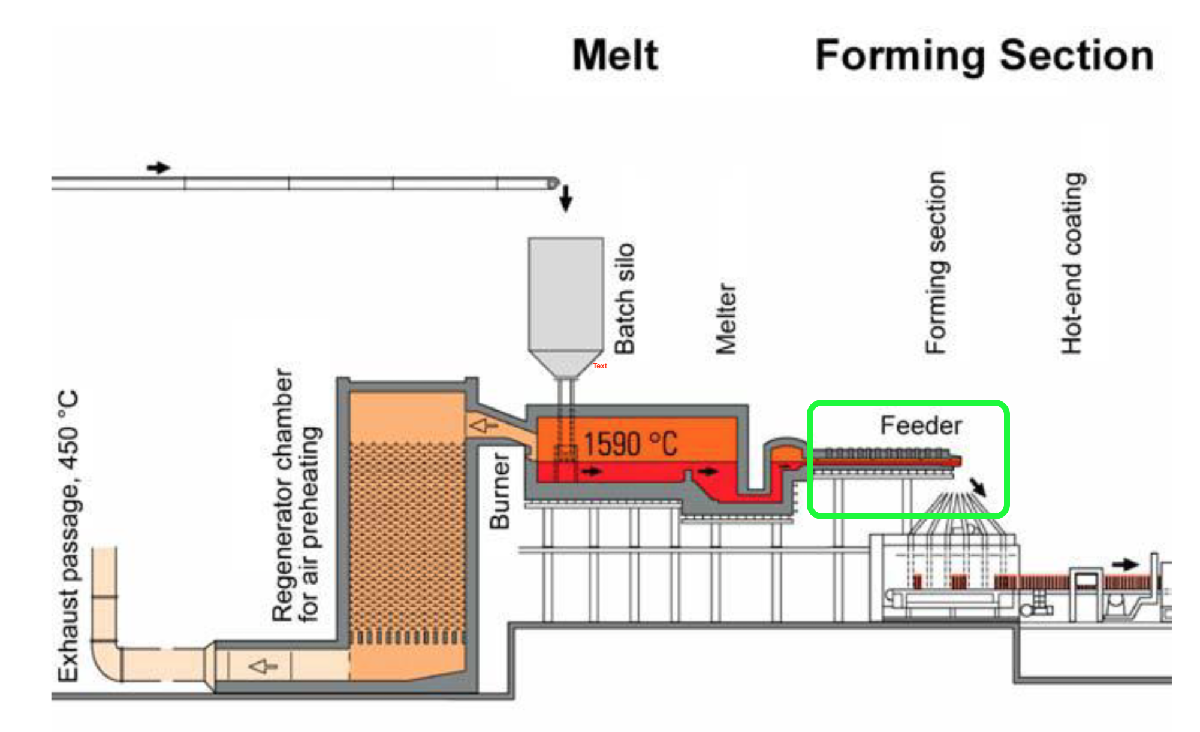

Typical industrial glass production plant, with in evidence the feeder. 

## Production of Melted Glass: the Feeder

- A feeder is the final part of a plant used for melting glass.

- Main purpose:  to realize a homogeneous temperature distribution of the glass at some absolute level that allows shaping of the glass.

- Structure of a feeder: it is divided into several sections in which energy can be supplied to  or extracted from the glass, using burners and cooling air.

## The Model

The model shall capture and describe  the dynamic relations between the inputs of the feeder (burners and cooling air jets in the various sections) and the outputs (glass temperatures close to the outlet).

### Important remarks

The process is a  distributed parameters dynamical system, but the model we are looking for is a lumped parameters model.	

The model set we choose for process identification (**ARX** model family) does not contain the mathematical description of the process (the so-called true parametrization). The present situation is one of the possible scenarios when facing system identification (for details, the reader may refer to the course topic "Asymptotic Theory for PEM Identification Methods" ).

## Data Description

- Available data: 1247 samples for each input and output variable;

- Sampling frequency: not declared. Let's assume the sampling time equal to 1 [unspecified time unit];

- 3 **inputs**:  the gas input of the first burner section of the feeder (input U1),cooling air input into the feeder (input U2) and the gas input of the second burner section of the feeder (input U3);

- 6 **outputs**: temperatures of the glass in a cross section of the feeder, close to the outlet;		

- Data source: [DaISy - Database for the Identification of Systems](https://homes.esat.kuleuven.be/~smc/daisy/), KU Leuven, BE;

### References:

- Van Overschee, Peter, and Bart De Moor. “N4SID: Subspace Algorithms for the Identification of Combined Deterministic-Stochastic Systems.” *Automatica*, vol. 30, no. 1, Jan. 1994, pp. 75–93, https://doi.org/10.1016/0005-1098(94)90230-5.

- Van Overschee Peter, *Subspace identification : Theory, Implementation, Application* , Ph.D. Thesis, K.U.Leuven, February 1995.

### Data preprocessing

Please, note: the authors have preprocessed the data. They removed the trend and the average value both from input and output data and finally, they scaled all the signals by dividing each signal by its standard deviation. The available data are actually **standard random variables** (0 as the mean value and 1 as the variance of each stochastic variable).		

## Initialisation

Let's clear the Matlab workspace and load the dataset.

% cleaning the Matlab workspace
close all
clear
clc

## Load Experimental Data 

First, load the time, the input and the output values. In this example, the experimental dataset was previously organized as a set of arrays (see the description in the code below) and then saved sa a .MAT file. 	

% loading the dataset
load glass_furnace_data.mat
% ------------------------------------------------------------
% variables in the MAT file:
%
% T <--> sample ID (correlated to the sampling time instants)
%        Remember: the sampling frequency is undeclared.
%
% U <--> inputs 
%        U(t, 1) <--> heating unit n. 1 
%        U(t, 2) <--> cooling input
%        U(t, 3) <--> heating unit n. 2 
%
% Y <--> outputs: 6 outputs from temperature sensors in 
%                 a cross section of the furnace
% 
% input_description, output_description <-> cell arrays with the labels of
%                                           each input and output variable
% 
% ---
%  MATLAB-code to retrieve the data from the original archive in DaISy
%
%	!gunzip glassfurnace.dat.Z
%	load glassfurnace.dat
%   T=glassfurnace(:,1);
%	U=glassfurnace(:,2:4);
%	Y=glassfurnace(:,5:10);
% ------------------------------------------------------------

NumData = size(T,1); % how many samples?
U1 = U(:, 1); % heating input n. 1 
U2 = U(:, 2); % cooling input
U3 = U(:, 3); % heating input n. 2 

Y1 = Y(:, 1); % temperature T_1
Y2 = Y(:, 2); % temperature T_2
Y3 = Y(:, 3); % temperature T_3
Y4 = Y(:, 4); % temperature T_4
Y5 = Y(:, 5); % temperature T_5
Y6 = Y(:, 6); % temperature T_6

### Plot the Data	 

fh_glassdata = figure('Name', 'Glass Furnace Dataset' , ...
         'Units','normalized', 'Position', [0, 0, 0.50, 0.99]);

ht(1) = subplot(6,1,1); % 1st plot
plot(T,U1, 'LineWidth',1.0, 'Color', [0 0.4470 0.7410]);
grid on; zoom on; 
xlim([min(T), max(T)]); ylim([1.25*min(U1), 1.25*max(U1)]);
title('Input 1');
xlabel('samples'); ylabel('U_1 [1]');
legend('heating input 1');
set(gca, 'FontSize', 16);

ht(2) = subplot(6,1,2); % 2nd plot
plot(T,U2, 'LineWidth',1.0, 'Color', [0.8500 0.3250 0.0980]);
grid on; zoom on; 
xlim([min(T), max(T)]); ylim([1.25*min(U2), 1.25*max(U2)]);
title('Input 2');
xlabel('samples'); ylabel('U_2 [1]');
legend('cooling input');
set(gca, 'FontSize', 16);

ht(3) = subplot(6,1,3); % 3rd plot
plot(T,U3, 'LineWidth',1.0, 'Color', [0.9290 0.6940 0.1250]);
grid on;zoom on; 
xlim([min(T), max(T)]); ylim([1.25*min(U3), 1.25*max(U3)]);
title('Input 3');
xlabel('samples'); ylabel('U_3 [1]');
legend('heating input 2');
set(gca, 'FontSize', 16);

ht(4) = subplot(6,1,[ 5, 6]); % the next image occupies 3 rows
plot(T, Y, 'LineWidth', 1.0)
title('Output signals: 6 temperature sensors');
xlabel('samples'); ylabel('temp. variation [1]');
grid on;zoom on; xlim([min(T), max(T)]);
legend({'T_1', 'T_2', 'T_3', ...
    'T_4', 'T_5', 'T_6'}, 'Orientation','horizontal');
output_description = {'temp. T_1', 'temp. T_2', 'temp. T_3', ...
     'temp. T_4', 'temp. T_5', 'temp. T_6'}';
set(gca, 'FontSize', 16);

 % The command linkaxes allows to zoom or pan in one subplot 
 % and display the same range of data in every subplot 
linkaxes(ht, 'x');

### Preparing the Data for the System Identification Procedure

Let's create a data structure for the System Identification algorithm with the experimental data. 

We want to identify a **model** describing the **dynamical relationship** between all the **inputs **$$U_1$$**, **$$U_2$$**, **$$U_3$$ and the **output **$$Y_1$$ 

data_set = iddata(Y1, U, 'OutputName',output_description{1},...
    'OutputUnit','deg C', 'InputName',{'U_1';'U_2';'U_3'},...
    'InputUnit',{'';'';''},'Tstart',1,...
    'SamplingInstants', T); 
% iddata object storing the whole dataset (data structure needed using the
% "System Identification" Matlab toolbox functions) 

Usually, the data must undergo a preprocessing process, removing the mean value from each variable's data sequence and any trends, if present. In this case, the data have already undergone this type of operation by the authors: the data we use all have zero mean value and unit variance.

% to remove average value and linear trend, uncomment and execute the code below
%
% [data_set_new, TrendDATA] = detrend(data_set); 
%
% data_set_new contains the new dataset, with zero mean and without linear trend. 
% The structure TrendDATA contains information on the original data set's average 
% value and linear trend. 

### To Do - Exercise 

Replicate the identification algorithm,  illustrated in the following part of this live script, with the aim to identify the  models describing the dynamical relationship between all the inputs $$U_1$$, $$U_2$$, $$U_3$$ and each of the remainig outputs $$Y_2\, , \; Y_3\,,\; \cdots Y_6$$$ . Modify in a proper way the `data_set` data structure and then execute the identification algorithm. Compare the obtained model with the one related to the output  $$Y_1$$. What are the similarities and what are the differences (if any) comparing the new model and the model corresponding to the output $$Y_1$$?

## The Identification of a "*Black Box*" Model

We want to identify a Multi-Input Single-Output (MISO) AutoRegressive with eXternal Inputs (**ARX**) ***black box***** model **$\mathcal{M}$, explaining the dynamics between all the inputs $$U_1$$, $$U_2$$, $$U_3$$ and the selected output $\bar{Y}$( in the original live script the first output$$Y_1$$, alternatively one of the remaining ouputs $$Y_2\, , \; Y_3\,,\; \cdots Y_6$$$):


$$\mathcal{M}\,:\; A(z)\,\bar{Y}(t) =  \sum_{j=1}^{3} B_{j}(z)\, U_{j}(t-1) + \epsilon(t)$$


For details on the structure of the model, please refer to the topic "*Predictors for ARX Models*" discussed later in the course. For detail on the training and validation phases and on the cross-validation function, please refer to the topics "*Least-Squares Batch Identification Algorithm*" and "*Choice of Models Complexity: Cross-Validation*" discussed later in the course.

### Choice of the Model Complexity

We have chosen the model family, but not yet its complexity. To find out the optimal complexity, we will use the cross-validation algorithm. 

#### Training and Validation Sets

As in Ref. [1], we divide the available data into two subsets: the **training set** and the **validation set**. Using the two subsets of data thus obtained, we apply **the cross-validation algorithm** to find **the optimal model complexity** in the chosen family (ARX).

trainSET_N = 700; % as in ref. [1] <--- split the dataset in training set and validation set

train_data = data_set(1:trainSET_N);     % the training set
valid_data = data_set(trainSET_N+1:end); % the validation set

#### How to Find the Optimal Model Complexity: the Cross-Validation Algorithm

The model family has been fixed (ARX models), but not the complexity: according to which criterion is it possible to choose the degree of the polynomials $A(z)$,  $B_1(z)$,  $B_2(z)$, and  $B_3(z)$?

Let's decide to explore every possible combination of the following configuration choices:

- degree of the polynomial $A(z)$: $n_a = 1\,,\; \cdots\,,\; 10$ , where $A(z) = 1-\sum_{i=1}^{n_a} a_i \, z^{-i}$

- degree of the polynomials  $B_1(z)$,  $B_2(z)$, and  $B_3(z)$: $n_{b}^{(j)} = 1\,,\; \cdots\,,\; 10 \,,\quad n_{d}^{(j)} = 1\,,\;\cdots\,,\;5 \quad j=1\,,\,2\,,\,3$, where $B_{j}(z) = \sum_{n=1}^{n_b} b_{n} \,z^{-(n-n_{d}^{(j)}+1)}$

Overall, we must analyse $1250000$ possible configurations to determine the optimal complexity.

The analysis can take several minutes, so to speed up the execution of the live script, we preferred to run the CV algorithm in advance to save the result in a file and load it directly. If you wish to apply the cross-validation algorithm to the search for the optimal complexity, uncomment the portion of the code below.

ARXcomplexity_struct = struc(1:10, 1:10, 1:10, 1:10, 1:5, 1:5, 1:5);
                       %      n_a  n_b1  n_b2  n_b3  n_d1 n_d2 n_d3

% ------------------------------------------
% Uncomment the code, starting from the next line, if you want to perfomr a
% cross- validatiion driven search for the optimal model complexity.
%{
% let's explore every possible configuration
tic
V_arx = arxstruc(train_data, valid_data, ARXcomplexity_struct);
elapsed_time_ARX_SYSID = toc; % how long did it take the algorithm?

auto_arx_best_CV = selstruc(V_arx, 0);
% select the best configuration, according to the cross-validation
% criterion

save glassFurnace_ARX_SYSID.mat train_data valid_data ...
     ARXcomplexity_struct V_arx elapsed_time_ARX_SYSID auto_arx_best_CV

% save the result
%}
% ------------------------------------------

load glassFurnace_ARX_SYSID
% Load the result of the previously performed cross-validation algorithm.

% ---- Cross Validation result ----
arxCV = arx(data_set, auto_arx_best_CV);
% the optimal model complexity, according the CV approach

fprintf(1, ...
    ['ARX models - optimal complexity according to the CV criterion- \n\r ', ...
     'n_a: %d \t n_b1: %d \t n_b2: %d \t n_b3: %d \n\r', ...
     'n_d1: %d \t n_d2: %d \t n_d3: %d \n'],...
    auto_arx_best_CV); % the resulting optimal complexity

fprintf(1,...
    'ARX models - CV algorithm -  elapsed time:\t %.2f [s]\n',...
    elapsed_time_ARX_SYSID); % elapsed time

### The best ARX model

We can now use the data to determine the best ARX model according to cross-validation.

arxCV = arx(data_set, auto_arx_best_CV);

Az_coeffs = num2str(arxCV.A);
B1z_coeffs = num2str(arxCV.B{1});
B2z_coeffs = num2str(arxCV.B{2});
B3z_coeffs = num2str(arxCV.B{3});

fprintf(1, ['*********************************** \n' ...
            'the best ARX model according to CV: \n'...
            'variable: %s \n ', ...
            'A(z) coeffs. : %s\n', ...
            'B1(z) coeffs. : \t    %s\n', ...
            'B2(z) coeffs. : \t    %s\n', ...
            'B3(z) coeffs. : \t    %s\n', ...
            '*********************************** \n'], ...
            arxCV.Variable, Az_coeffs, B1z_coeffs, B2z_coeffs, B3z_coeffs);

### Model performance

To evaluate the performance of the obtained model, we use it as a one-step forward predictor and compare the prediction with the observed data.

compareOPT = compareOptions('InitialCondition', 'z');

pred_HorizonN = 1; % N step ahead prediction
[YP_CV, fitCV] = compare(arxCV, data_set,  pred_HorizonN ,compareOPT);

#### Model output compared with the measured data

fh = figure; set(fh,'Name','1-step-ahead prediction', ...
        'Units','normalized', 'Position', [0.2, 0, 0.75, 0.85]);
plot(Y1, 'Color','k','LineWidth', 1.0, ...
    'DisplayName', 'measured data: temp. $T_1(n)$'); hold on;
plot(YP_CV.OutputData, 'LineWidth', 1.0, ...
    'DisplayName', ...
    ['1-step ahead pred $\hat{T}_{1}(n|n-1)$: fit $', num2str(fitCV), '$ \%']);
xlim([1, numel(Y1)]);
hleg = legend('show');
set(hleg, 'Interpreter','latex');
set(gca, 'FontSize', 16);

grid on
xlabel('samples'); 
ylabel('measured $T_1(n)$ vs predicted $\hat{T}_{1}(n|n-1)$', ...
    'Interpreter','Latex')

#### Prediction error

fh_predERR = figure; set(fh_predERR,'Name','1-step-ahead prediction', ...
        'Units','normalized', 'Position', [0.2, 0, 0.75, 0.85]);

subplot(2,1,1);
plot(Y1, 'Color','k','LineWidth', 1.0, ...
    'DisplayName', 'measured data: temp. $T_1(n)$'); hold on;
plot(YP_CV.OutputData, 'LineWidth', 1.0, ...
    'DisplayName', ...
    '1-step ahead pred $\hat{T}_{1}(n|n-1)$');
xlim([1, numel(Y1)]);
hleg = legend('show');
set(hleg, 'Interpreter','latex');
set(gca, 'FontSize', 16);
grid on
xlabel('samples'); 
ylabel('temperature T [$^{\circ}$C]', ...
    'Interpreter','Latex')

subplot(2,1,2);
plot(Y1-YP_CV.OutputData, 'LineWidth', 1.0, ...
    'DisplayName', 'prediction error: $T_1(n)-\hat{T}_{1}(n|n-1)$');
xlim([1, numel(Y1)]);
hleg = legend('show');
set(hleg, 'Interpreter','latex');
set(gca, 'FontSize', 16);
grid on
xlabel('samples'); 
ylabel('prediction error [$^{\circ}$C]', ...
    'Interpreter','Latex')